% logreader.m
% Use this script to read data from your micro SD card

clear;
%clf;

filenum = '016'; % file number for the data you want to read
infofile = strcat('data/inf', filenum, '.TXT');
datafile = strcat('data/log', filenum, '.BIN');

## map from datatype to length in bytes

dataSizes.('float') = 4;
dataSizes.('ulong') = 4;
dataSizes.('int') = 4;
dataSizes.('int32') = 4;
dataSizes.('uint8') = 1;
dataSizes.('uint16') = 2;
dataSizes.('char') = 1;
dataSizes.('bool') = 1;

## read from info file to get log file structure

fileID = fopen(infofile);
items = textscan(fileID,'%s','Delimiter',',','EndOfLine','\r\n');
fclose(fileID);
[ncols,~] = size(items{1});
ncols = ncols/2;
varNames = items{1}(1:ncols)';
varTypes = items{1}(ncols+1:end)';
varLengths = zeros(size(varTypes));
colLength = 256;
for i = 1:numel(varTypes)
    varLengths(i) = dataSizes.(varTypes{i});
end
R = cell(1,numel(varNames));

## read column-by-column from datafile

fid = fopen(datafile,'rb');
for i=1:numel(varTypes)
    %# seek to the first field of the first record
    fseek(fid, sum(varLengths(1:i-1)), 'bof');
    
    %# % read column with specified format, skipping required number of bytes
    R{i} = fread(fid, Inf, ['*' varTypes{i}], colLength-varLengths(i));
    eval(strcat(varNames{i},'=','R{',num2str(i),'};'));
end
fclose(fid);

accelXog = accelX

accelXog = 3987×1 single column vector
   147
   155
   151
    19
   268
   635
   264
   420
   245
   167


accelYog = accelY

accelYog = 3987×1 single column vector
    37
    21
   -71
  -325
  -134
   -13
   -24
  -130
  -149
   -44


accelZog = accelZ

accelZog = 3987×1 single column vector
         997
         947
         830
         791
         771
         865
         728
        1064
         763
        1033


accelX = accelX(595:999);
accelY = accelY(595:999);
accelZ = accelZ(595:999);

accelX = accelX .* 0.0100951891;
accelY = accelY .* 0.0100951891;
accelZ = accelZ .* 0.0100951891;

[h, p, ci, stats] = ttest2(accelZ, accelX)

h = single
1

p = single
0

ci = 2×1 single column vector
   -1.1121
   -1.0805


stats = struct with fields:
    tstat: -136.4024
       df: 500
       sd: 0.0900


accelZ

accelZ = 251×1 single column vector
    9.6712
    9.7116
    9.7116
    9.8731
    9.6712
    9.7520
    9.7923
    9.8327
    9.7923
    9.6409


indices = find(motorB > 0)

indices =    633
   634
   635
   636
   637
   638
   639
   640
   641
   642


indices(length(indices))

ans = 999

## Process your data here

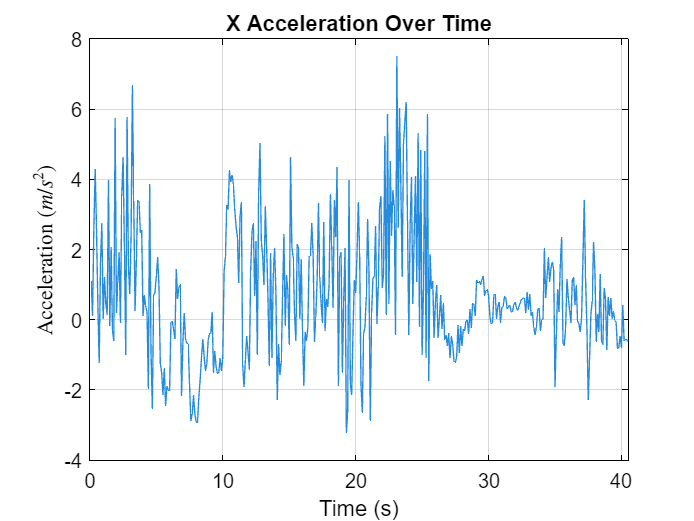

plt = plot((1:size(accelX))./10, accelX);
ax = gca;
ax.XAxis(1).Limits = [0 length(accelX)/10];
set(gca, 'Color', [1 1 1])
set(gca, "XColor", [0 0 0])
set(gca, "YColor", [0 0 0])
grid on
chartTitle = "X Acceleration Over Time";
xlabel("Time (s)", "Color", [0 0 0]);
ylabel("Acceleration $ \left( m/s^{2} \right)$", 'Interpreter', 'latex', "Color", [0 0 0]);
title(chartTitle, "Color", [0 0 0]);

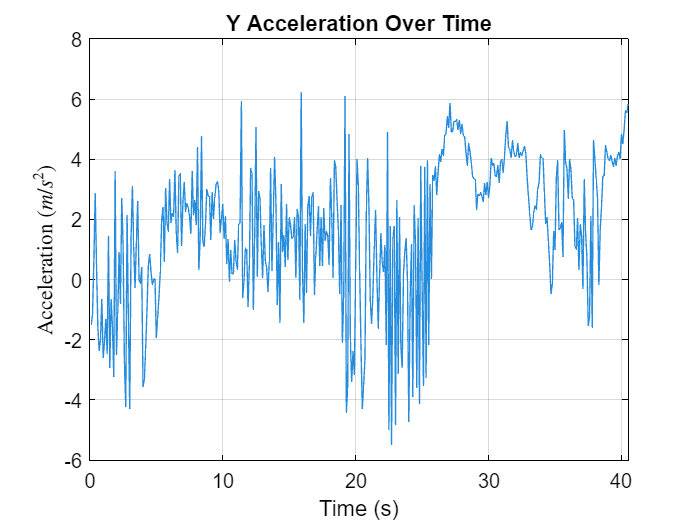

plt = plot((1:size(accelY))./10, accelY);
ax = gca;
ax.XAxis(1).Limits = [0 length(accelY)/10];
set(gca, 'Color', [1 1 1])
set(gca, "XColor", [0 0 0])
set(gca, "YColor", [0 0 0])
grid on
chartTitle = "Y Acceleration Over Time";
title(chartTitle, "Color", [0 0 0]);
xlabel("Time (s)", "Color", [0 0 0]);
ylabel("Acceleration $ \left( m/s^{2} \right)$", 'Interpreter', 'latex', "Color", [0 0 0]);

accelZog = accelZog.*0.0100951891

accelZog = 3987×1 single column vector
   10.0649
    9.5601
    8.3790
    7.9853
    7.7834
    8.7323
    7.3493
   10.7413
    7.7026
   10.4283


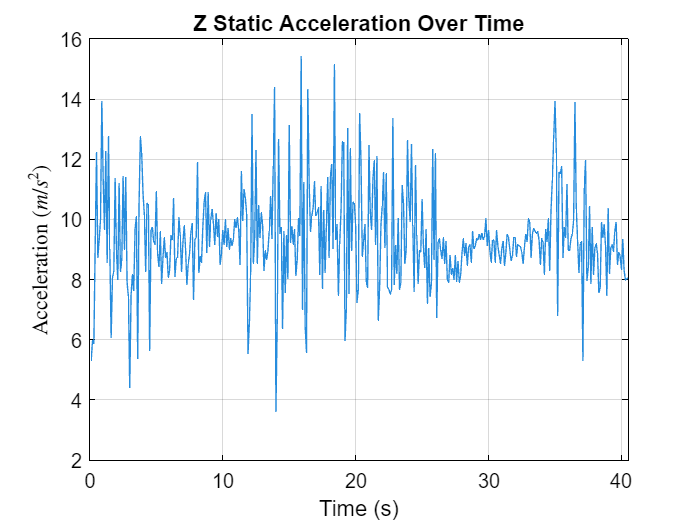

plt = plot((1:size(accelZ))./10, accelZ);
ax = gca;
ax.XAxis(1).Limits = [0 length(accelZ)/10];
set(gca, 'Color', [1 1 1])
set(gca, "XColor", [0 0 0])
set(gca, "YColor", [0 0 0])
grid on
chartTitle = "Z Static Acceleration Over Time";
title(chartTitle, "Color", [0 0 0]);
xlabel("Time (s)", "Color", [0 0 0]);
ylabel("Acceleration $ \left( m/s^{2} \right)$", 'Interpreter', 'latex', "Color", [0 0 0]);

## Analysis

zmean = mean(accelZ) % takes the average of the values collected for Z acceleration
zstd = std(accelZ) % Applies the standard deviation formula to the dataset
zse = zstd/sqrt(length(accelZ)) % Divide the standard deviation by the 
% square root of the number of datapoints to get the standard error

xmean = mean(accelX)
ymean = mean(accelY)

zmean = mean(accelZ)

alpha = 0.05; % For a 95% confidence interval
t_critical = tinv(1 - alpha/2, length(accelZ)-1) % Calculate the appropriate t-value for

t_critical = 1.9659

% N-1 degrees of freedom

margin_error = t_critical * zse % multiply the t-value by the standard error to get the margin of error

Unrecognized function or variable 'zse'.

CI_lower = zmean- margin_error % calculate the lower bound from the z mean
CI_upper = zmean + margin_error % calculate the upper bound from the z mean

max(accelZ)-9.81

ans = single
5.6154